## Zestaw 4

Ad 1

    Generowanie losowego digrafu zespołu(n, p)

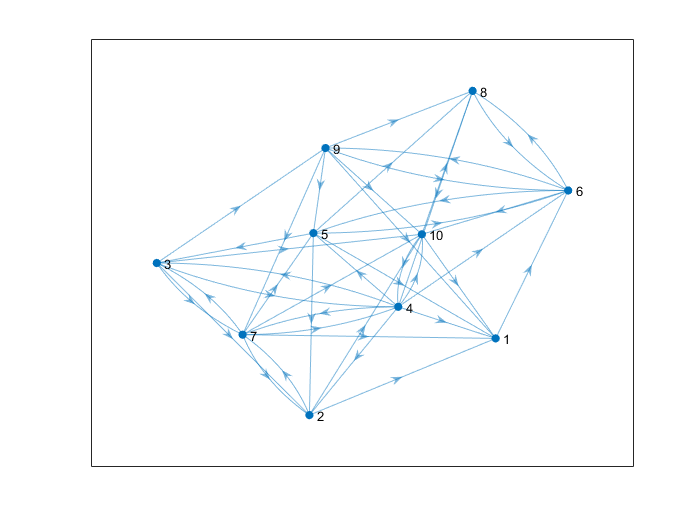

n = 10;
p = 0.5;
digraph1 = genRandDigraph(n, p);
plot(digraph1);

digraph1.getAdjacencyMatrix()

ans =      0     0     0     0     0     1     0     0     0     0
     1     0     0     0     0     0     1     0     0     1
     0     1     0     1     0     0     1     0     1     1
     1     1     1     0     1     1     1     0     0     1
     1     1     1     0     0     1     0     1     0     0
     0     0     0     0     1     0     0     1     1     1
     1     1     1     1     1     0     0     0     0     1
     0     0     0     1     0     1     0     0     0     0
     1     0     0     0     1     1     1     1     0     1
     1     0     0     1     0     0     0     1     0     0


Ad 2

    Wyznaczanie spójnych składowych algorytmem Kosaraju

comp = kosaraju(digraph1)

comp =      1     1     1     1     1     1     1     1     1     1


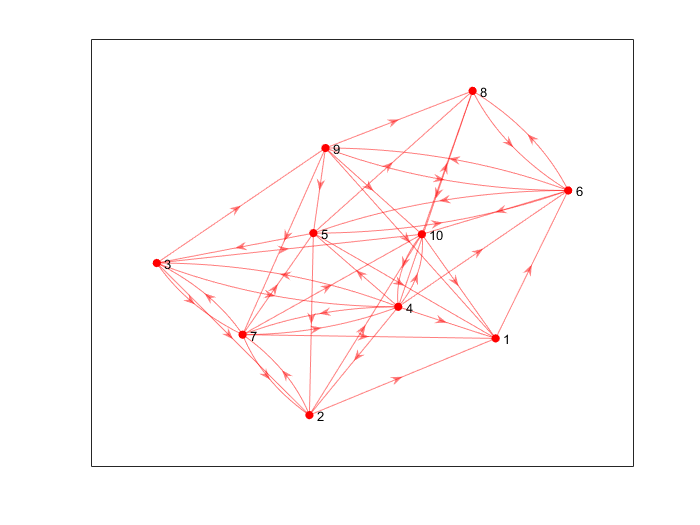

h = plot(digraph1);
nodes = digraph1.Nodes;
ncomp1 = nodes(comp==1);
for i=1:length(ncomp1)
    mdigraph = digraph1.getDigraph();
    nbors = successors(mdigraph,ncomp1(i));
    highlight(h,ncomp1(i),intersect(nbors, ncomp1),'EdgeColor','r');
end
highlight(h,ncomp1,'NodeColor','r');

highlight(h,nodes(comp==2),'NodeColor','g');
ncomp2 = nodes(comp==2);
for i=1:length(ncomp2)
    mdigraph = digraph1.getDigraph();
    nbors = successors(mdigraph,ncomp2(i));
    highlight(h,ncomp2(i),intersect(nbors, ncomp2),'EdgeColor','g');
end
highlight(h,nodes(comp==3),'NodeColor','m');
ncomp3 = nodes(comp==3);
for i=1:length(ncomp3)
    mdigraph = digraph1.getDigraph();
    nbors = successors(mdigraph,ncomp3(i));
    highlight(h,ncomp3(i),intersect(nbors, ncomp3),'EdgeColor','m');
end

Ad 3

    Algorytm Bellmana-Forda

if max(comp)==1
    noEdges = length(digraph1.Edges(1,:));
    weights = randi(10,[1, noEdges]);

Aby uniknąć ujemnych cyklów liczba krawędzi z wagami mniejszymi jest znacząco mniejsza od liczby krawędzi z wagami dodatnimi

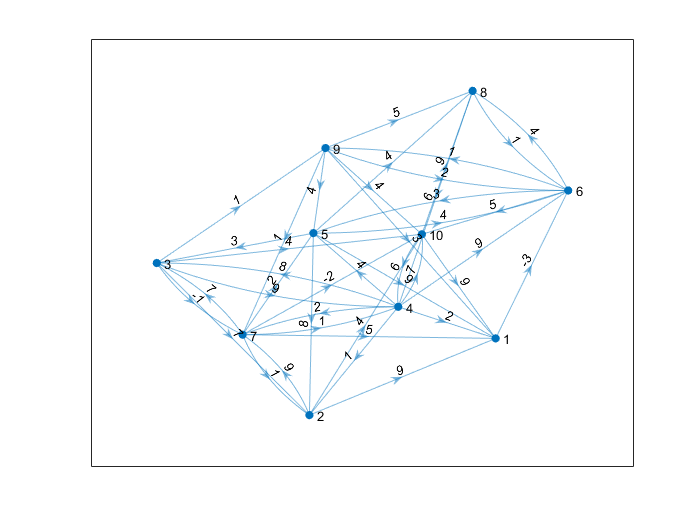

D =      0     0     3     0     0    -3    -1     1    -2    -3
     9     0    12     9     9     6     8    10     7     4
     2     0     0     0     1    -1    -1     3     0    -3
     2     1     5     0     2    -1     1     3     0    -1
     5     3     3     3     0     2     2     4     3     0
     4     3     6     3     3     0     2     4     1     0
     3     1     5     1     2     0     0     4     1    -2
     5     4     7     4     4     1     3     0     2     1
     3     2     6     2     3     0     1     4     0    -1
     8     7    11     6     8     5     7     9     6     0


P =      0     7     5     7     6     1     9     6     6     7
     2     0     5     7     6     1     9     6     6     2
     4     7     0     7     7     1     3     6     6     7
     4     4     5     0     6     1     9     6     6     7
     4     7     5     7     0     1     3     5     6     7
     9     7     5     7     6     0     9     6     6     7
     4     7     5     7     7     1     0     6     6     7
     9     7     5     7     6     8     9     0     6     7
     9     7     5     7     7     1     9     6     0     7
     4     4     5    10     6     1     9    10     6     0


    noEdgesMinus= round(sqrt(n));
    for i=1:noEdgesMinus
        weights(randi(noEdges)) = -randi(5);
    end
    digraph1.Edges = [digraph1.Edges; weights];
    plot(digraph1.getDigraph(),'EdgeLabel',weights);
    [D, P] = johnson(digraph1)
else
    error("Digraf nie jest silnie spójny! Proszę spróbować inny")
end